### 初始化

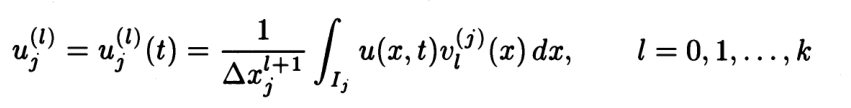

function U = Uinitial(u0,num)

global Center
global Element
global hstep



basefun0 = @(i,x) 1;
basefun1 = @(i,x) x-Center(i);
basefun2 = @(i,x) (x-Center(i)).^2-1/12*hstep^2;

U = zeros(num+2,3);
for i = 2:num+1

    a_i = Element(i,1);
    b_i = Element(i,2);

    int1 = quadgk(@(x) u0(x).*basefun0(i,x), a_i, b_i);
    U(i,1) = int1 / hstep;

    int2 = quadgk(@(x) u0(x).*basefun1(i,x), a_i, b_i);
    U(i,2) = int2 / hstep^2;

    int3 = quadgk(@(x) u0(x).*basefun2(i,x), a_i, b_i);
    U(i,3) = int3 / hstep^3;
end

end